clear; clc; close all;

Test 1

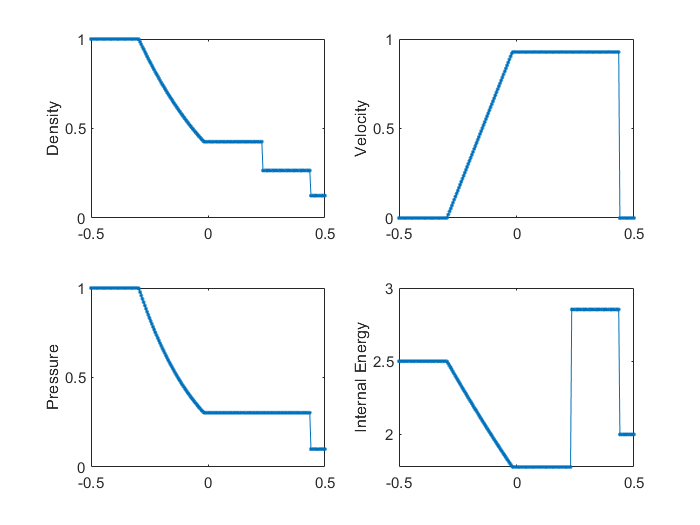

[u, p, sampler] = riemann_solver(1.0,0.0,1.0,0.125,0.0,0.1,1.4);
x = linspace(-0.5,0.5,201).';
sampler_t = @(x)(sampler(x,0.25));
[rhom,um,pm] = arrayfun(sampler_t, x);

subplot(2,2,1),plot(x,rhom,'.-'),ylabel('Density');
subplot(2,2,2),plot(x,um,'.-'),ylabel('Velocity');
subplot(2,2,3),plot(x,pm,'.-'),ylabel('Pressure');
subplot(2,2,4),plot(x,pm./rhom./(1.4-1),'.-'),ylabel('Internal Energy');

Test 2

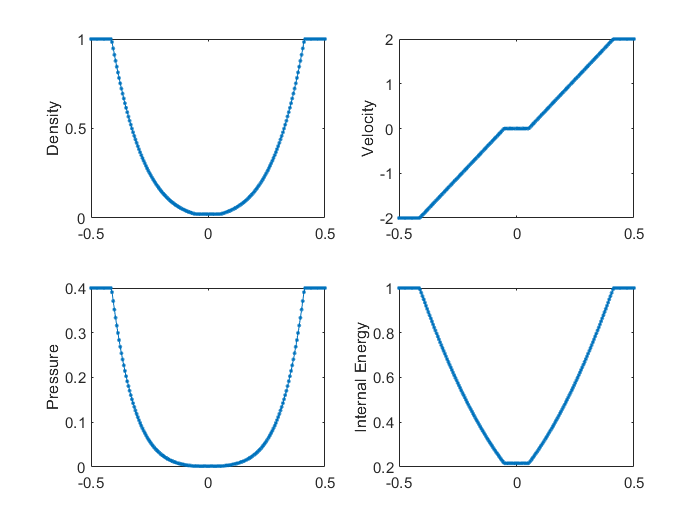

[u, p, sampler] = riemann_solver(1.0,-2.0,0.4,1.0,2.0,0.4,1.4);
x = linspace(-0.5,0.5,201).';
sampler_t = @(x)(sampler(x,0.15));
[rhom,um,pm] = arrayfun(sampler_t, x);

subplot(2,2,1),plot(x,rhom,'.-'),ylabel('Density');
subplot(2,2,2),plot(x,um,'.-'),ylabel('Velocity');
subplot(2,2,3),plot(x,pm,'.-'),ylabel('Pressure');
subplot(2,2,4),plot(x,pm./rhom./(1.4-1),'.-'),ylabel('Internal Energy');

Test 3

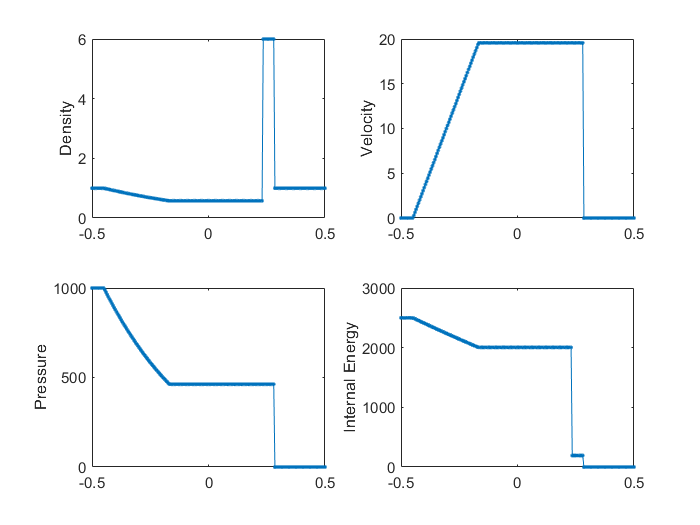

[u, p, sampler] = riemann_solver(1.0,0.0,1000.0,1.0,0.0,0.01,1.4);
x = linspace(-0.5,0.5,201).';
sampler_t = @(x)(sampler(x,0.012));
[rhom,um,pm] = arrayfun(sampler_t, x);

subplot(2,2,1),plot(x,rhom,'.-'),ylabel('Density');
subplot(2,2,2),plot(x,um,'.-'),ylabel('Velocity');
subplot(2,2,3),plot(x,pm,'.-'),ylabel('Pressure');
subplot(2,2,4),plot(x,pm./rhom./(1.4-1),'.-'),ylabel('Internal Energy');

Test 4

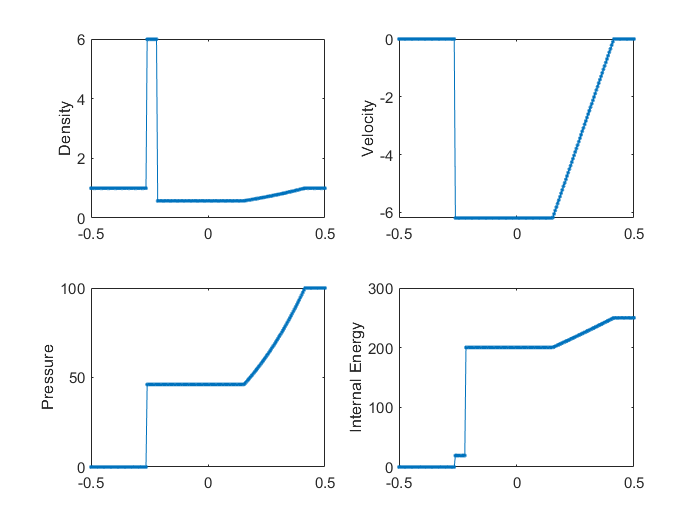

[u, p, sampler] = riemann_solver(1.0,0.0,0.01,1.0,0.0,100.0,1.4);
x = linspace(-0.5,0.5,201).';
sampler_t = @(x)(sampler(x,0.035));
[rhom,um,pm] = arrayfun(sampler_t, x);

subplot(2,2,1),plot(x,rhom,'.-'),ylabel('Density');
subplot(2,2,2),plot(x,um,'.-'),ylabel('Velocity');
subplot(2,2,3),plot(x,pm,'.-'),ylabel('Pressure');
subplot(2,2,4),plot(x,pm./rhom./(1.4-1),'.-'),ylabel('Internal Energy');

Test 5

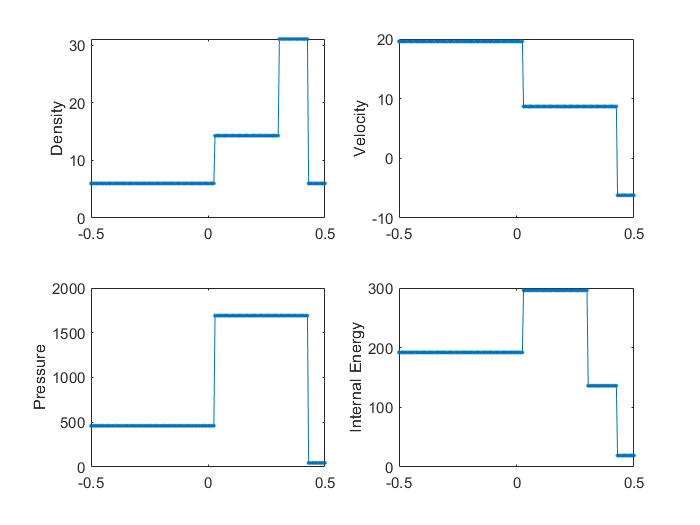

[u, p, sampler] = riemann_solver(5.99924,19.5975,460.894,5.99242,-6.19633,46.0950,1.4);
x = linspace(-0.5,0.5,201).';
sampler_t = @(x)(sampler(x,0.035));
[rhom,um,pm] = arrayfun(sampler_t, x);

subplot(2,2,1),plot(x,rhom,'.-'),ylabel('Density');
subplot(2,2,2),plot(x,um,'.-'),ylabel('Velocity');
subplot(2,2,3),plot(x,pm,'.-'),ylabel('Pressure');
subplot(2,2,4),plot(x,pm./rhom./(1.4-1),'.-'),ylabel('Internal Energy');